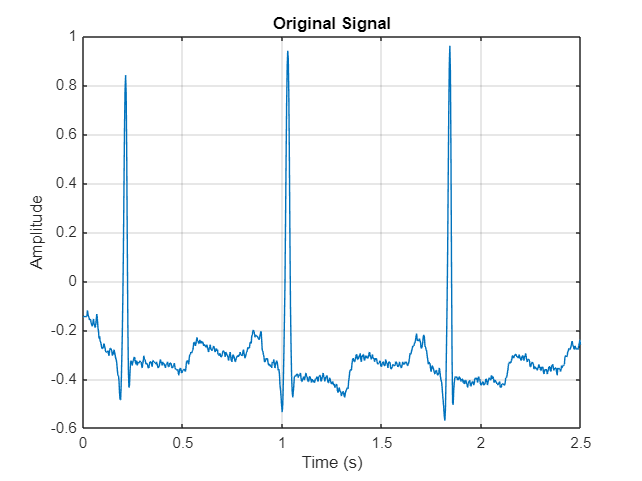

% PAN TOMKINS ALGORITHM

% FUNCTION DEFINITIONS

% FILTERS
% LOW PASS FILTER
function y = low_pass_filter(x)
    N = length(x); % Length of the input sequence
    y = zeros(size(x)); % Initialize output
    for n = 13:N
        y(n) = 2 * y(n-1) - y(n-2) + x(n) - 2 * x(n-6) + x(n-12);
    end
end

% HIGH PASS FILTER
function y = high_pass_filter(x)
    N = length(x); % Length of the input sequence
    y = zeros(size(x)); % Initialize output
    for n = 33:N
        y(n) = y(n-1) - (1/32) * x(n) + x(n-16) - x(n-17) + (1/32) * x(n-32);
    end
end

% DERIVATIVE
function y = derivative(x)
    N = length(x); % Length of the input sequence
    y = zeros(size(x)); % Initialize output
    for n = 5:N  % Start at n=5 because of the x(n-4) term
        y(n) = (1/8) * (2*x(n) + x(n-1) - x(n-3) - 2*x(n-4));
    end
end

% SQUARING
function y = square(x)
    N = length(x); % Length of the input sequence
    y = zeros(size(x)); % Initialize output
    for n = 1:N
        y(n) = x(n)^2; % Square each sample
    end
end

% SLIDING WINDOW INTEGRATION
function y = integration(x)
    % Formula: y(n) = (1/30) * sum(x(n-29), ..., x(n))
    % Initialize variables
    N = length(x);
    y = zeros(1, N); % Output signal
    % Define the window size (30 samples as per the equation)
    window_size = 30;
    % Apply the integration filter
    for n = window_size:N
        % Sum the last 30 samples and divide by 30 to get the average
        y(n) = sum(x(n - window_size + 1:n)) / window_size;
    end
    % For the first few samples (less than 30), the filter cannot apply fully,
    % so we just set the output to zero
    y(1:window_size-1) = 0;
end

% PEAK DETECTION
function [r_peaks, heart_rate] = peak_detection(x, fs)
    % PEAK_DETECTION_HW - Implements hardware-compatible R-peak detection with adaptive thresholds.
    % Inputs:
    %   x  - Integrated ECG signal after preprocessing
    %   fs - Sampling frequency (Hz)
    % Outputs:
    %   r_peaks - Detected R-peak indices
    %   heart_rate - Estimated heart rate (bpm)
    
    N = length(x);
    r_peaks = []; % Store detected R-peak locations
    rr_intervals = zeros(1, 8); % Store last 8 RR intervals
    
    % Initial threshold values
    SPKI = max(x) * 0.25;  % Initial signal peak estimate
    NPKI = max(x) * 0.125; % Initial noise peak estimate
    
    THRESHOLD1 = NPKI + 0.25 * (SPKI - NPKI);
    THRESHOLD2 = 0.5 * THRESHOLD1; % Secondary threshold for search-back

    last_peak = 0;
    
    for n = 2:N-1
        % Check if current sample is a local maximum (peak detection)
        if x(n) > x(n-1) && x(n) > x(n+1)
            PEAKI = x(n); % Detected peak
            
            if PEAKI > THRESHOLD1
                % Ensure minimum RR interval (to reject noise & T-waves)
                if isempty(r_peaks) || (n - last_peak) > round(0.6 * fs)
                    r_peaks = [r_peaks, n]; % Store R-peak index
                    last_peak = n;
                    
                    % Update SPKI (signal peak estimate)
                    SPKI = 0.125 * PEAKI + 0.875 * SPKI;
                end
            else
                % Update NPKI (noise peak estimate)
                NPKI = 0.125 * PEAKI + 0.875 * NPKI;
            end
            
            % Update Thresholds
            THRESHOLD1 = NPKI + 0.25 * (SPKI - NPKI);
            THRESHOLD2 = 0.5 * THRESHOLD1;
        end
    end
    
    % Compute Heart Rate
    if length(r_peaks) > 1
        rr_intervals = diff(r_peaks) / fs;
        heart_rate = 60 ./ rr_intervals; % Convert RR intervals to BPM
    else
        heart_rate = 0;
    end
    heart_rate = mean(heart_rate);
end

% MAIN PROGRAM
[tm,signal,fs,labels]=rdmat('100m');
ch1=signal(:,1);
ch2=signal(:,2);
t=tm(1:900);
s1=ch1(1:900);
s2=ch2(1:900);

x = s1;
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal');
grid on;

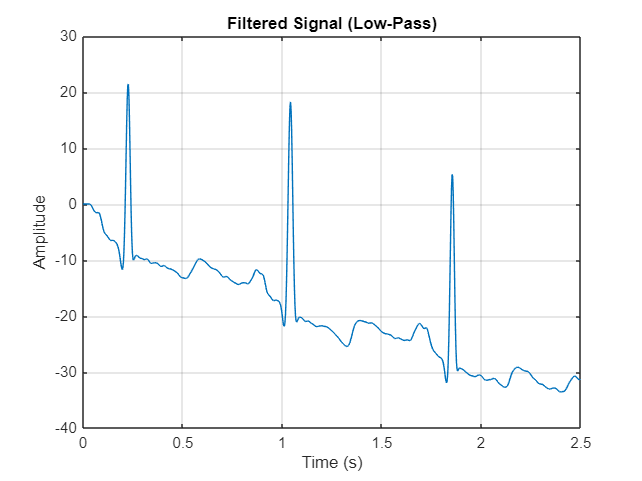


y = low_pass_filter(x);
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (Low-Pass)');
grid on;

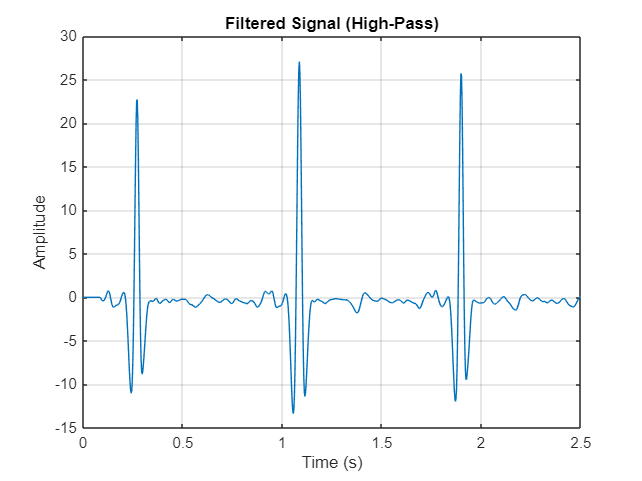


y = high_pass_filter(y);
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (High-Pass)');
grid on;

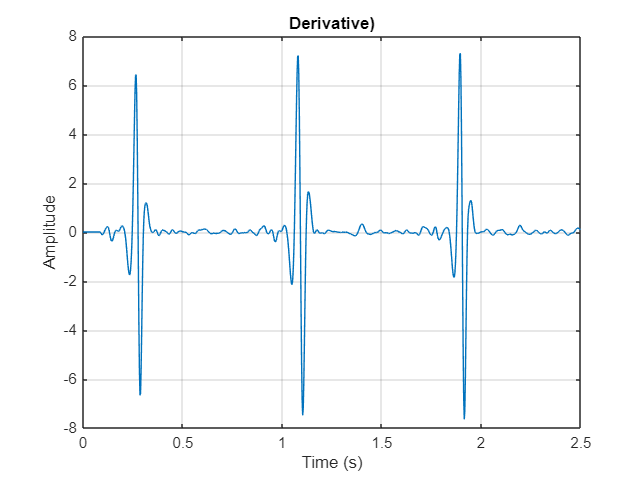


y = derivative(y);
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Derivative)');
grid on;

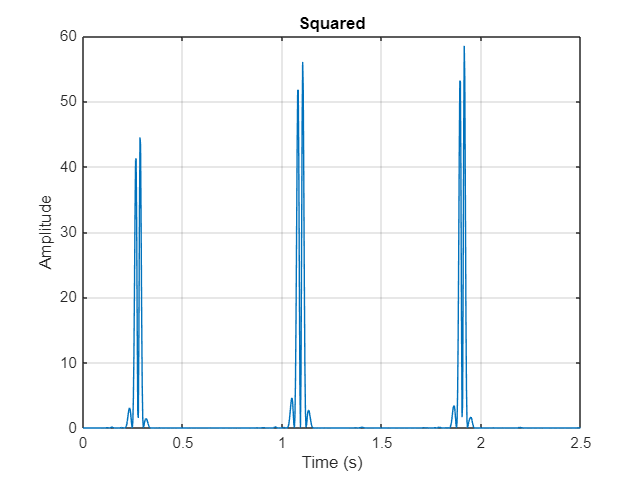


y = square(y);
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Squared');
grid on;

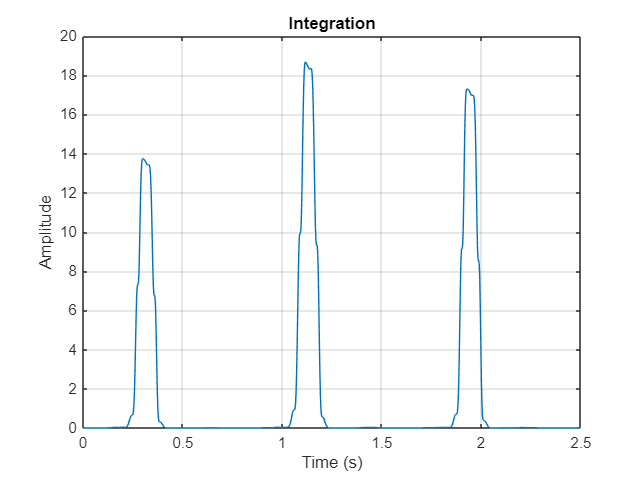


y = integration(y);
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Integration');
grid on;

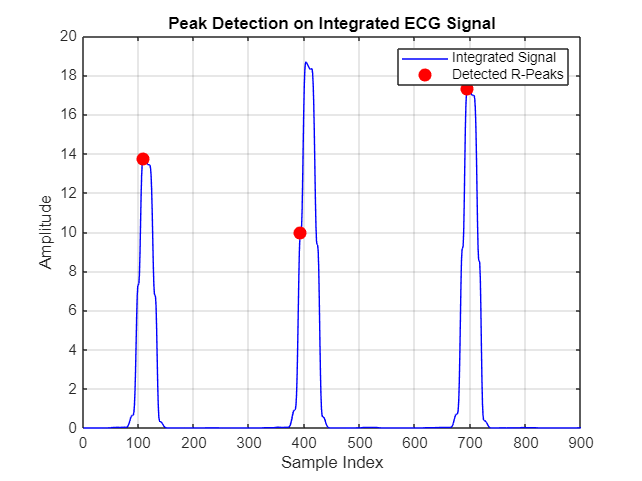


[r_peaks, heart_rate] = peak_detection(y, fs);
% Plot Integrated ECG Signal and Detected Peaks
figure;
plot(y, 'b'); % Plot integrated ECG signal
hold on;
plot(r_peaks, y(r_peaks), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Plot detected peaks
xlabel('Sample Index');
ylabel('Amplitude');
title('Peak Detection on Integrated ECG Signal');
legend('Integrated Signal', 'Detected R-Peaks');
grid on;
hold off;

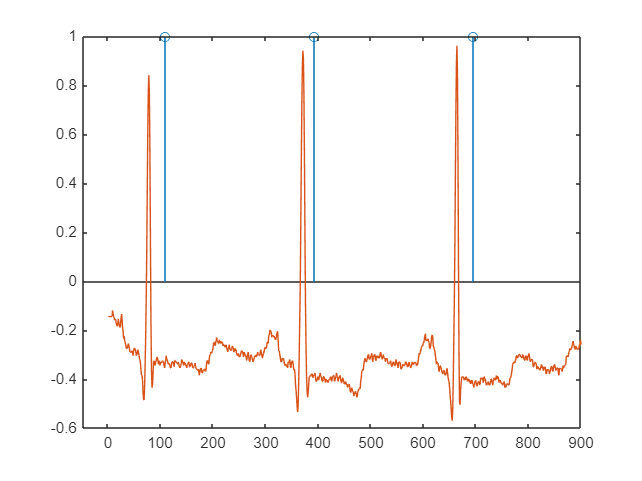


N = length(y);

z=ones(1,N);
stem(r_peaks, z(r_peaks));
hold on
plot(x);


% peaks are detected (ignore the latency)
